# SASNE running example

data = readmatrix('data/imbalanced_test.txt');

[sasne_out,Z] = SASNE(data);

constructing graph...
Elapsed time is 0.465786 seconds.
computing graph distance...
Elapsed time is 0.390717 seconds.
computing tsne embedding...
Elapsed time is 2.374954 seconds.
Total running time 3.2364 seconds


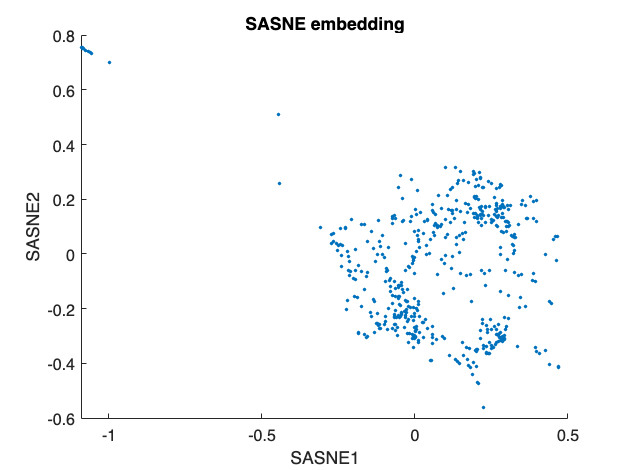

figure
scatter(sasne_out(:,1),sasne_out(:,2),5,'filled')
title('SASNE embedding')
xlabel('SASNE1')
ylabel('SASNE2')

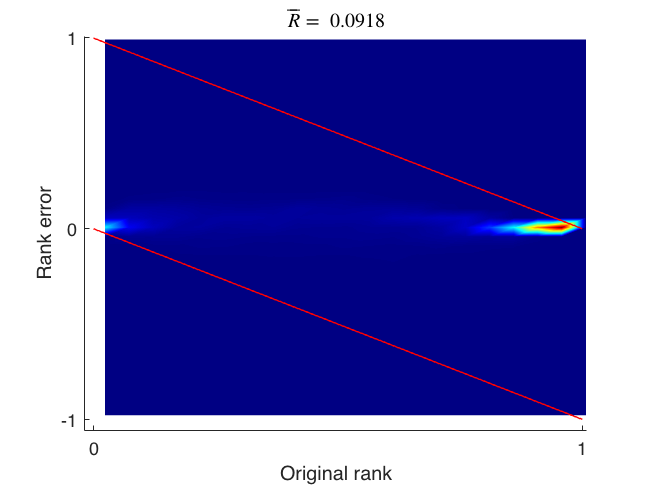

D_original = pdist(Z,'euclidean');
D_sasne = pdist(sasne_out,'euclidean');
RRP(D_original,D_sasne);

clear D_original D_sasne ans